# Machine Learning Online Class

## =============== Part 1: Loading movie ratings dataset ================

fprintf('Loading movie ratings dataset.\n\n');

Loading movie ratings dataset.




%  Load data
load ('ex8_movies.mat');

%  Y is a 1682x943 matrix, containing ratings (1-5) of 1682 movies on 
%  943 users
%
%  R is a 1682x943 matrix, where R(i,j) = 1 if and only if user j gave a
%  rating to movie i

%  From the matrix, we can compute statistics like average rating.
fprintf('Average rating for movie 1 (Toy Story): %f / 5\n\n', ...
        mean(Y(1, R(1, :))));

Average rating for movie 1 (Toy Story): 3.878319 / 5



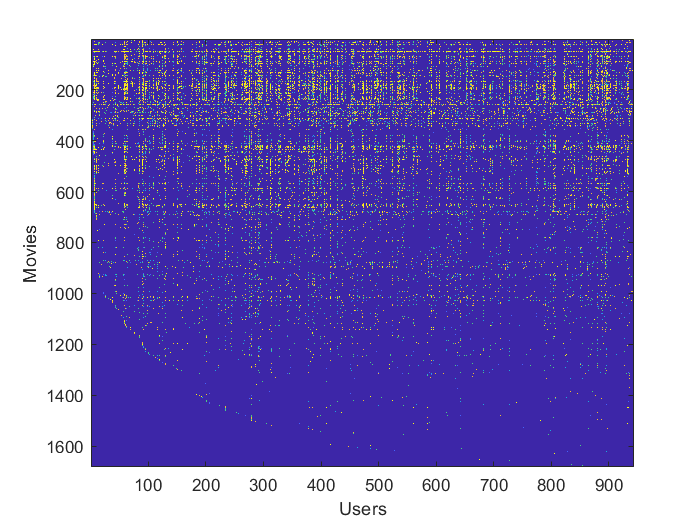


%  We can "visualize" the ratings matrix by plotting it with imagesc
imagesc(Y);
ylabel('Movies');
xlabel('Users');


fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## ============ Part 2: Collaborative Filtering Cost Function ===========

%  Load pre-trained weights (X, Theta, num_users, num_movies, num_features)
load ('ex8_movieParams.mat');

%  Reduce the data set size so that this runs faster
num_users = 4; num_movies = 5; num_features = 3;
X = X(1:num_movies, 1:num_features);
Theta = Theta(1:num_users, 1:num_features);
Y = Y(1:num_movies, 1:num_users);
R = R(1:num_movies, 1:num_users);

%  Evaluate cost function
J = cofiCostFunc([X(:) ; Theta(:)], Y, R, num_users, num_movies, ...
               num_features, 0);
           
fprintf(['Cost at loaded parameters: %f '...
         '\n(this value should be about 22.22)\n'], J);

Cost at loaded parameters: 22.224604 
(this value should be about 22.22)



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## ============== Part 3: Collaborative Filtering Gradient ==============

fprintf('\nChecking Gradients (without regularization) ... \n');


Checking Gradients (without regularization) ... 



%  Check gradients by running checkNNGradients
checkCostFunction;

    0.7341    0.7341
   -0.5498   -0.5498
    0.8902    0.8902
   -0.4852   -0.4852
   -1.1714   -1.1714
    2.4295    2.4295
    0.6581    0.6581
    2.5213    2.5213
    1.8310    1.8310
   -2.2021   -2.2021
    1.1077    1.1077
   -2.2980   -2.2980
   -0.1441   -0.1441
         0         0
   -3.8730   -3.8730
    0.0147    0.0147
   -1.4664   -1.4664
   -0.0117   -0.0117
         0         0
    1.7624    1.7624
    0.1739    0.1739
    0.4710    0.4710
    1.6567    1.6567
         0         0
   -3.3322   -3.3322
    0.3090    0.3090
   -0.9921   -0.9921

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your cost function implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 1.25267e-12



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## ========= Part 4: Collaborative Filtering Cost Regularization ========

%  Evaluate cost function
J = cofiCostFunc([X(:) ; Theta(:)], Y, R, num_users, num_movies, ...
               num_features, 1.5);
           
fprintf(['Cost at loaded parameters (lambda = 1.5): %f '...
         '\n(this value should be about 31.34)\n'], J);

Cost at loaded parameters (lambda = 1.5): 672126.326394 
(this value should be about 31.34)



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## ======= Part 5: Collaborative Filtering Gradient Regularization ======

%  
fprintf('\nChecking Gradients (with regularization) ... \n');


Checking Gradients (with regularization) ... 



%  Check gradients by running checkNNGradients
checkCostFunction(1.5);

    5.1392    5.1392
   -0.0476   -0.0476
    1.3002    1.3002
    5.4200    5.4200
   -3.0814   -3.0814
    1.1242    1.1242
   -0.0442   -0.0442
    2.7977    2.7977
    0.1205    0.1205
   -2.4311   -2.4311
   -0.7162   -0.7162
    7.0021    7.0021
   -0.2511   -0.2511
   -4.7040   -4.7040
   -4.6747   -4.6747
    5.2507    5.2507
   -1.2969   -1.2969
    0.0522    0.0522
   -1.5374   -1.5374
    1.0237    1.0237
    4.0528    4.0528
    1.8487    1.8487
    2.2559    2.2559
   -3.9215   -3.9215
   -1.0301   -1.0301
    2.1034    2.1034
    0.3696    0.3696

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your cost function implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 1.81033e-12



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## ============== Part 6: Entering ratings for a new user ===============

movieList = loadMovieList();

%  Initialize my ratings
my_ratings = zeros(1682, 1);

% Check the file movie_idx.txt for id of each movie in our dataset
% For example, Toy Story (1995) has ID 1, so to rate it "4", you can set
my_ratings(1) = 4;

% Or suppose did not enjoy Silence of the Lambs (1991), you can set
my_ratings(98) = 2;

% We have selected a few movies we liked / did not like and the ratings we
% gave are as follows:
my_ratings(7) = 3;
my_ratings(12)= 5;
my_ratings(54) = 4;
my_ratings(64)= 5;
my_ratings(66)= 3;
my_ratings(69) = 5;
my_ratings(183) = 4;
my_ratings(226) = 5;
my_ratings(355)= 5;

fprintf('\n\nNew user ratings:\n');
for i = 1:length(my_ratings)
    if my_ratings(i) > 0 
        fprintf('Rated %d for %s\n', my_ratings(i), ...
                 movieList{i});
    end
end

fprintf('\nProgram paused. Press enter to continue.\n');
pause;

## ================== Part 7: Learning Movie Ratings ====================

fprintf('\nTraining collaborative filtering...\n');

%  Load data
load('ex8_movies.mat');

%  Y is a 1682x943 matrix, containing ratings (1-5) of 1682 movies by 
%  943 users
%
%  R is a 1682x943 matrix, where R(i,j) = 1 if and only if user j gave a
%  rating to movie i

%  Add our own ratings to the data matrix
Y = [my_ratings Y];
R = [(my_ratings ~= 0) R];

%  Normalize Ratings
[Ynorm, Ymean] = normalizeRatings(Y, R);

%  Useful Values
num_users = size(Y, 2);
num_movies = size(Y, 1);
num_features = 10;

% Set Initial Parameters (Theta, X)
X = randn(num_movies, num_features);
Theta = randn(num_users, num_features);

initial_parameters = [X(:); Theta(:)];

% Set options for fmincg
options = optimset('GradObj', 'on', 'MaxIter', 100);

% Set Regularization
lambda = 10;
theta = fmincg (@(t)(cofiCostFunc(t, Ynorm, R, num_users, num_movies, ...
                                num_features, lambda)), ...
                initial_parameters, options);

% Unfold the returned theta back into U and W
X = reshape(theta(1:num_movies*num_features), num_movies, num_features);
Theta = reshape(theta(num_movies*num_features+1:end), ...
                num_users, num_features);

fprintf('Recommender system learning completed.\n');

fprintf('\nProgram paused. Press enter to continue.\n');
pause;

## ================== Part 8: Recommendation for you ====================

p = X * Theta';
my_predictions = p(:,1) + Ymean;

movieList = loadMovieList();

[r, ix] = sort(my_predictions, 'descend');
fprintf('\nTop recommendations for you:\n');
for i=1:10
    j = ix(i);
    fprintf('Predicting rating %.1f for movie %s\n', my_predictions(j), ...
            movieList{j});
end

fprintf('\n\nOriginal ratings provided:\n');
for i = 1:length(my_ratings)
    if my_ratings(i) > 0 
        fprintf('Rated %d for %s\n', my_ratings(i), ...
                 movieList{i});
    end
end